% Paper Figures
% AUTHOR: Kambadur Ananthamurthy
% DETAILS: 333 uniquely tagged synthetic datasets were analysed on the basis
% of a variety of numerical procedures. Cells in each dataset were given
% analog scores on the same basis.
% Load the Consolidated Analysis Details and look for patterns in the plots.

close all
clear

tic

## Plots - I

Generating Example Schematics ...
Reference Dataset - M26_5_4 | Date: 20180514
Total cells: 135
Loading existing event library ...
... done!
Dataset: 1
Dataset: 2
Dataset: 3
Dataset: 4
Dataset: 5
Dataset: 6
Dataset: 7
Dataset: 8
Saving example ...
... done!
... Example created.


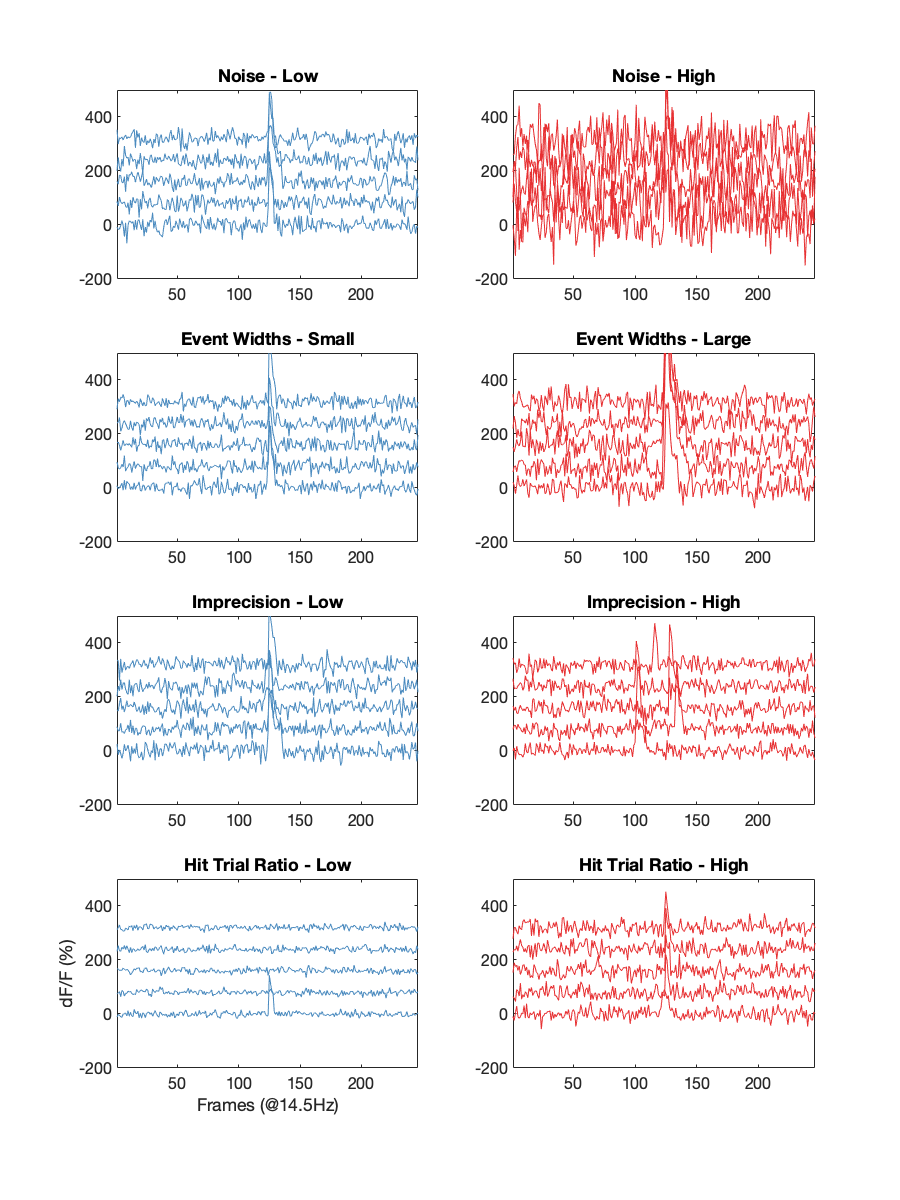

generateSyntheticDataExample

## Subsequent plots

input.nCells = 135;
input.nAlgos = 8;
input.nMethods = 6;

workingOnServer = 1; %Only to select the batch for datasets

if workingOnServer == 1 %Bebinca
    % Synthetic Dataset Details
    input.gDate = 20210824; %generation date
    input.gRun = 1; %generation run number
    input.nDatasets = 333;
    
    % Consolidated Analysis Details
    input.cDate = 20210918; %consolidation date
    input.cRun = 1; %consolidation run number
    
elseif workingOnServer == 2 %Adama
    % Synthetic Dataset Details
    input.gDate = 20210903; %generation date
    input.gRun = 1; %generation run number
    input.nDatasets = 333;
    
    % Consolidated Analysis Details
    input.cDate = 20210911; %consolidation date
    input.cRun = 1; %consolidation run number
end

workingOnServer = 0; %Current
diaryOn         = 0;


% Directory config

if workingOnServer == 1
    HOME_DIR = '/home/bhalla/ananthamurthy/';
    saveDirec = strcat(HOME_DIR, 'Work/Analysis/Imaging/');
elseif workingOnServer == 2
    HOME_DIR = '/home/ananth/Documents/';
    HOME_DIR2 = '/home/ananth/Desktop/';
    saveDirec = strcat(HOME_DIR2, 'Work/Analysis/Imaging/');
else
    HOME_DIR = '/Users/ananth/Documents/';
    HOME_DIR2 = '/Users/ananth/Desktop/';
    saveDirec = strcat(HOME_DIR2, 'Work/Analysis/Imaging/');
end
%Additinal search paths
addpath(genpath(strcat(HOME_DIR, 'rho-matlab/CustomFunctions')))
addpath(genpath(strcat(HOME_DIR, 'rho-matlab/localCopies')))
make_db

saveFolder = strcat(saveDirec, db.mouseName, '/', db.date, '/');

if diaryOn
    if workingOnServer == 1
        diary (strcat(HOME_DIR, '/logs/benchmarksDiary'))
    else
        diary (strcat(HOME_DIR2, '/logs/benchmarksDiary_', num2str(gDate), '_', num2str(gRun)))
    end
    diary on
end


% Operations
plotRefQ = 1;
plotAnalysedQs = 1;
plotDatasetCheck = 0;

% Load Synthetic Data
disp('Loading synthetic datasets ...')

Loading synthetic datasets ...


synthDataFilePath = sprintf('%s/synthDATA_%i_gRun%i_batch_%i.mat', ...
    saveFolder, ...
    input.gDate, ...
    input.gRun, ...
    input.nDatasets);
load(synthDataFilePath)
disp('... done!')

... done!




% Load Analysis Results
disp('Loading analysis results ...')

Loading analysis results ...


analysisFilePath = sprintf('%s/synthDATA_Analysis_%i_cRun%i_cData.mat', ...
    saveFolder, ...
    input.cDate, ...
    input.cRun);
load(analysisFilePath)
disp('... done!')

... done!



input.removeNaNs = 0;
input.saveFolder = saveFolder;
[Y, X] = developConfusionMatrix(input, sdo_batch, cData);

Creating Confusion Matrix ...
... done!



% TP, FN, FP, TN
nCases = length(Y);

%Preallocation
allTP = zeros(nCases, input.nAlgos);
allTN = zeros(nCases, input.nAlgos);
allFP = zeros(nCases, input.nAlgos);
allFN = zeros(nCases, input.nAlgos);
TPR = zeros(input.nAlgos, 1); %Sensitivity
FPR = zeros(input.nAlgos, 1); %Fall-out or False Positive Rate
TNR = zeros(input.nAlgos, 1); %Specificity
FNR = zeros(input.nAlgos, 1); %Miss Rate
PPV = zeros(input.nAlgos, 1); %Positive Predictive Value
NPV = zeros(input.nAlgos, 1); %Negative Predictive Value
FDR = zeros(input.nAlgos, 1); %False Discovery Rate
FOR = zeros(input.nAlgos, 1); %Flase Omission Rate
PT = zeros(input.nAlgos, 1); %Prevalence Threshold
TS = zeros(input.nAlgos, 1); %Threat Score or Critical Success Index (CSI)
ACC = zeros(input.nAlgos, 1); %Accuracy
BA = zeros(input.nAlgos, 1); %Balanced Accuracy

results1 = zeros(input.nAlgos, 4);
results2 = zeros(input.nAlgos, 4);
results3 = zeros(input.nAlgos, 3);

confusionMatrix = zeros(input.nAlgos, 2, 2);

for algo = 1:input.nAlgos
    for myCase = 1:nCases
        if Y(myCase) %Positive Cases
            if X(myCase, algo)
                allTP(myCase, algo) = 1;
            else
                allFN(myCase, algo) = 1;
            end
        else %Negative Cases
            if X(myCase, algo)
                allFP(myCase, algo) = 1;
            else
                allTN(myCase, algo) = 1;
            end
        end
    end
    
    TP = sum(allTP(:, algo));
    FN = sum(allFN(:, algo));
    FP = sum(allFP(:, algo));
    TN = sum(allTN(:, algo));
    
    confusionMatrix(algo, 1, 1) = FN;
    confusionMatrix(algo, 1, 2) = TP;
    confusionMatrix(algo, 2, 1) = TN;
    confusionMatrix(algo, 2, 2) = FP;
    
    TPR(algo) = TP/(TP + FN);
    FPR(algo) = FP/(FP + TN);
    TNR(algo) = TN/(TN + FP);
    FNR(algo) = FN/(FN + TP);
    
    PPV(algo) = TP/(TP + FP);
    NPV(algo) = TN/(TN + FN);
    FDR(algo) = FP/(FP + TP);
    FOR(algo) = FN/(FN + TN);
    
    PT(algo) = (sqrt(TPR(algo)*(-TNR(algo) +1)) + TNR(algo) - 1)/(TPR(algo) + TNR(algo) -1);
    TS(algo) = TP/(TP + FN + FP);
    
    ACC(algo) = (TP + TN)/(TP + TN + FP + FN);
    BA(algo) = (TPR(algo) + TNR(algo))/2;
    
    results1(algo, 1) = TPR(algo);
    results1(algo, 2) = FPR(algo);
    results1(algo, 3) = TNR(algo);
    results1(algo, 4) = FNR(algo);
    
    results2(algo, 1) = TPR(algo);
    results2(algo, 2) = TNR(algo);
    results2(algo, 3) = FDR(algo);
    results2(algo, 4) = FOR(algo);
    
    results3(algo, 1) = TPR(algo);
    results3(algo, 2) = PPV(algo);
    results3(algo, 3) = 2 * results3(algo, 1) * results3(algo, 2)/(results3(algo, 1) + results3(algo, 2));
end

% Search for uniquely identified Time Cells with some threshold
unique1 = zeros(length(Y), input.nAlgos);
unique2 = zeros(length(Y), input.nAlgos);
unique3 = zeros(length(Y), input.nAlgos);
for obs = 1:length(Y)
    if sum(squeeze(X(obs, :))) == 1
        unique1(obs, :) = X(obs, :);
    elseif sum(squeeze(X(obs, :))) == 2
        unique2(obs, :) = X(obs, :);
    elseif sum(squeeze(X(obs, :))) == 3
        unique3(obs, :) = X(obs, :);
    end
end

input.plotOptimalPoint = 0;
figureDetails = compileFigureDetails(16, 2, 5, 0.2, 'inferno'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
%Extra colormap options: inferno/plasma/viridis/magma
%C = distinguishable_colors(input.nMethods);
C = linspecer(input.nMethods);

%disp('Generating subplot 1 ...')
input.removeNaNs = 1;

%Prepare the Look Up Table (LUT)
[response, predictor] = getTheTable(sdo_batch, cData, input);

Creating Look Up Table ...
... done!



%Normalize
maxima = max(predictor);
normPredictor = predictor./maxima;

%Z-Score
zPredictor = zscore(predictor);

% Normalize Z-Score
maxima = max(zPredictor);
nzPredictor = zPredictor./maxima;

% % Ruggero G. Bettinardi (2021). getCosineSimilarity(x,y)
% % (https://www.mathworks.com/matlabcentral/fileexchange/62978-getcosinesimilarity-x-y),
% % MATLAB Central File Exchange. Retrieved October 5, 2021.
%
% % When data points are sparse in the sense that some scores are undefined/missing,
% % it is often better to use cosine similiarity between the pairwise scores across all method pairs.
%
% cosineSimilarityMatrix1 = nan(input.nMethods, input.nMethods);
% cosineSimilarityMatrix2 = nan(input.nMethods, input.nMethods);
% Z = normPredictor;
% for method1 = 1:input.nMethods
%     x = Z(:, method1);
%     tf = isnan(x);
%     %x(tf) = [];
%     for method2 = 1:input.nMethods
%         y = Z(:, method2);
%         cosineSimilarityMatrix1(method1, method2) = getCosineSimilarity(x(~tf), y(~tf));
%     end
% end

correlationMatrix = corrcoef(normPredictor, 'Rows', 'pairwise');
%correlationMatrix = corrcoef(predictor);

%Labels
algoLabels = {'A-Boot', 'B-Boot', 'C-Boot', 'C-Otsu', 'D-Otsu', 'E-Otsu', 'F-Boot', 'F-Otsu'};
concordanceAlgoLabels = {'>=1', '>=2', '>=3', '>= 4', '>= 5', '>= 6', '>=7', '>=8'};
metricLabels = {'Recall', 'Precision', 'F1 Score'};
methodLabels = {'R2B (A)', 'TI (B)', 'Peak AUC/Std (C)', 'PCA (D)', 'SVM (E)', 'Param. Eqs. (F)'};
methodLabels2 = {'A', 'B', 'C', 'D', 'E', 'F'};
legends1 = {'TPR', 'FPR', 'TNR', 'FNR'};

## Plots - IV

disp('Plotting Scores and Comparisions ...')

Plotting Scores and Comparisions ...


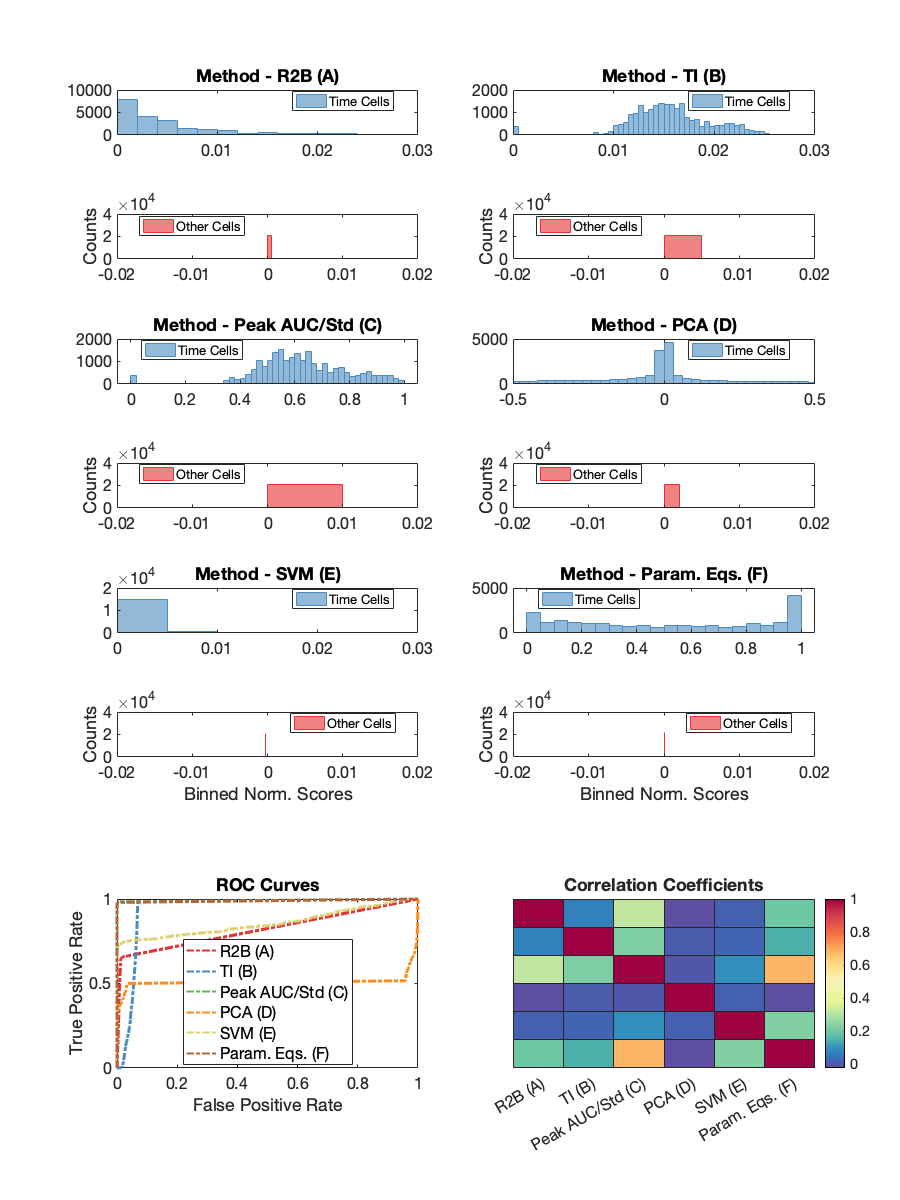

fig4 = figure(4);
clf
set(fig4, 'Position', [1000, 300, 900, 1200])
title(sprintf('Comparative Analysis (N=%i)', input.nDatasets), ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')


for method = 1:input.nMethods
    ptcScores = normPredictor(response == 1, method);
    ocScores = normPredictor(response == 0, method);
    
    if method == 1
        subplotNum = 1;
    elseif method == 2
        subplotNum = 2;
    elseif method == 3
        subplotNum = 9;
    elseif method == 4
        subplotNum = 10;
    elseif method == 5
        subplotNum = 17;
    elseif method == 6
        subplotNum = 18;
    end
    
    subplot(16, 2, subplotNum)
    histogram(ptcScores, ...
        'EdgeColor', C(2, :), ...
        'FaceColor', C(2, :))
    %     ylabel('Counts', ...
    %         'FontSize', figureDetails.fontSize, ...
    %         'FontWeight', 'bold')
    hold off
    title(sprintf('Method - %s', char(methodLabels(method))), ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    if method == 3 || method == 6
        %do nothing
    elseif method == 4
        xlim([-0.5, 0.5])
    else
        xlim([0, 0.03])
    end
    lgd = legend({'Time Cells'}, ...
        'Location', 'best');
    lgd.FontSize = figureDetails.fontSize-3;
    set(gca, 'FontSize', figureDetails.fontSize)
    
    subplot(16, 2, subplotNum+4)
    histogram(ocScores, ...
        'EdgeColor', C(1, :), ...
        'FaceColor', C(1, :))
    ylabel('Counts', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    hold off
    if method == 5 || method == 6
        xlabel('Binned Norm. Scores', ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    end
    xlim([-0.02, 0.02])
    lgd = legend({'Other Cells'}, ...
        'Location', 'best');
    lgd.FontSize = figureDetails.fontSize-3;
    set(gca, 'FontSize', figureDetails.fontSize)
    
end
hold off

subplot(16, 2, [27, 29, 31])

%for method = input.nMethods:-1:1
for method = 1:input.nMethods
    %disp(method)
    %Linear Regression
    clear Mdl
    Mdl = fitglm(predictor(:, method), response, ...
        'Distribution', 'binomial', ...
        'Link', 'logit');
    
    %Get the scores
    score_log = Mdl.Fitted.Probability;
    
    %ROC Curve coordinates
    [Xlog, Ylog, Tlog, AUClog, optOP] = perfcurve(response, score_log, 1);
    %disp(Xlog)
    %disp(Ylog)
    %disp(optOP)
    
    %     if isnan(Xlog) || isnan(Ylog)
    %         warning('Probably skipping ...')
    %     end
    
    %Plots
    plot(Xlog, Ylog, '-.', ...
        'Color', C(method, :), ...
        'LineWidth', figureDetails.lineWidth)
    hold on
    
    if input.plotOptimalPoint
        try
            plot(optOP(1), optOP(2), 'Color', C(method, :), 'o')
        catch
            warning('Unable to plot optimal oprational point')
        end
        hold on
    end
end
hold off
% title(sprintf('ROC Curves (N=%i)', input.nDatasets), ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
title('ROC Curves', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('False Positive Rate', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('True Positive Rate', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
lgd1 = legend(methodLabels, ...
    'Location', 'best');
lgd1.FontSize = figureDetails.fontSize;

set(gca, 'FontSize', figureDetails.fontSize)

%subplot(3, 9, 24:26)
subplot(16, 2, [28, 30, 32])
h = heatmap(correlationMatrix, ...
    'Colormap', linspecer, ...
    'Title', 'Correlation Coefficients', ...
    'CellLabelColor','none');
h.XDisplayLabels = methodLabels;
%h.YDisplayLabels = methodLabels2;
h.YDisplayLabels = {'', '', '', '', '', ''};
set(gca, 'FontSize', figureDetails.fontSize)

print(sprintf('%s/ComparingScores-%i-%i-%i-%i-%i_%i', ...
    HOME_DIR2, ...
    input.gDate, ...
    input.gRun, ...
    input.nDatasets, ...
    input.cDate, ...
    input.cRun, ...
    workingOnServer), ...
    '-dpng')


disp('... Scores and Comparisons Plotted')

... Scores and Comparisons Plotted


## Plots - V

disp('Plotting Performance Metrics ...')

Plotting Performance Metrics ...


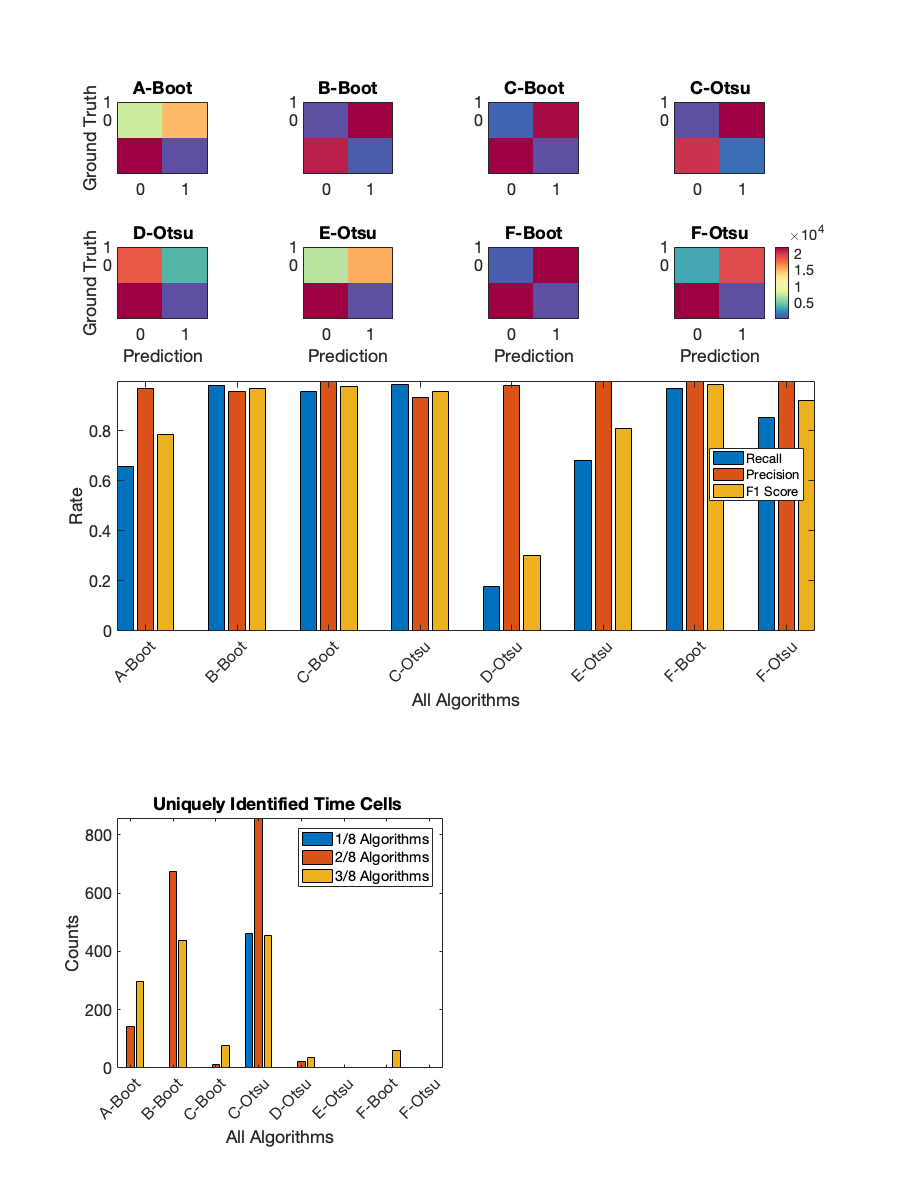


fig5 = figure(5);
clf
set(fig5, 'Position', [600, 300, 900, 1200])
title('Confusion Matrices and Performance Evalutation', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
for algo = 1:input.nAlgos
   
    subplot(7, 4, algo)
%     h = heatmap(squeeze(confusionMatrix(algo, :, :)), ...
%         'Colormap', linspecer, ...
%         'Title', sprintf('%s', char(algoLabels(algo))), ...
%         'CellLabelColor','none');
%     h.XDisplayLabels = {'0', '1'};
%     h.YDisplayLabels = {'0', '1'};
    
    imagesc(squeeze(confusionMatrix(algo, :, :)))
    title(sprintf('%s', char(algoLabels(algo))), ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    colorbar
    colormap(linspecer)
    if algo ~= 8 && algo ~= 4
        set(colorbar,'visible','off')
    end
    xticklabels({'0', '1'})
    yticklabels({'1', '0'})
    if algo > 4
        %h.XLabel = 'Prediction';
        xlabel('Prediction', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    end
    if algo == 1 || algo == 5
        %h.YLabel = 'Ground Truth';
        ylabel('Ground Truth', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    end
    set(gca, 'FontSize', figureDetails.fontSize)
end

subplot(7, 4, [9:12, 13:16])
d = bar(results3);
xlim([0 5])
axis tight
% title('Prediction Performance Metrics', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
xlabel('All Algorithms', ...
'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Rate', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticklabels(algoLabels)
xtickangle(45)
lgd = legend({'Recall', 'Precision', 'F1 Score'}, ...
    'Location', 'best');
lgd.FontSize = figureDetails.fontSize-3;
set(gca, 'FontSize', figureDetails.fontSize)


allUnique = zeros(input.nAlgos, 3);
allUnique(:, 1) = sum(unique1, 1);
allUnique(:, 2) = sum(unique2, 1);
allUnique(:, 3) = sum(unique3, 1);
subplot(7, 4, [21:22, 25:26])
bar(allUnique)
xlim([1, 8])
axis tight
title('Uniquely Identified Time Cells ', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('All Algorithms', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Counts', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticklabels(algoLabels)
xtickangle(45)
%set(gca,'xtick',[])
legend({'1/8 Algorithms', '2/8 Algorithms', '3/8 Algorithms'})
set(gca, 'FontSize', figureDetails.fontSize)


% Runtime and profile

Error using callstats
Cannot change the history while logging is enabled.

Error in profile (line 146)
    callstats('history', history);

Error in runBatchAnalysis (line 14)
profile on -history

subplot(7, 4, [23:24, 27:28])

print(sprintf('%s/PerformanceEvaluation-%i-%i-%i_%i', ...
    HOME_DIR2, ...
    input.gDate, ...
    input.gRun, ...
    input.nDatasets, ...
    workingOnServer), ...
    '-djpeg')

disp('... Performance Metrics Plotted')

## Plots VI

disp('Plotting Sensitivity and Resource ...')

nSets = 3;

iNoise1 = (298:300); %low
iNoise2 = (301:303); %medium
iNoise3 = (304:306); %high

iEW1 = (307:309); %small
iEW2 = (310:312); %medium
iEW3 = (313:315); %large

iImp1 = (316:318); %low
iImp2 = (319:321); %medium
iImp3 = (322:324); %high

iHTR1 = (325:327); %low
iHTR2 = (328:330); %medium
iHTR3 = (331:333); %high

fig6 = figure(6);
clf
set(fig6, 'Position', [1500, 300, 900, 1200])

[Y1, X1] = developConfusionMatrix4Effects(input, sdo_batch, cData, iNoise1);
[Y2, X2] = developConfusionMatrix4Effects(input, sdo_batch, cData, iNoise2);
[Y3, X3] = developConfusionMatrix4Effects(input, sdo_batch, cData, iNoise3);
results3Line = zeros(input.nAlgos, nSets);

nShuffles = 3;
for iSet = 1:nSets
    if iSet == 1
        X = X1;
        Y = Y1;
    elseif iSet == 2
        X = X2;
        Y = Y2;
    elseif iSet == 3
        X = X3;
        Y = Y3;
    end
    for shuffle = 1:nShuffles
        if shuffle == 1
            myCells = 1:input.nCells;
        elseif shuffle == 2
            myCells = input.nCells+1: input.nCells*2;
        elseif shuffle == 3
            myCells = (input.nCells*2)+1: input.nCells*3;
            [results1, results2, results3] = compareAgainstTruth(X(myCells, :), Y(myCells), input);
        end
        
        bundledResults3(shuffle, :, iSet) = results3(:, 3);
    end
end

meanBundledResults3 = squeeze(mean(bundledResults3, 1, 'omitnan'));
stdBundledResults3 = squeeze(std(bundledResults3, 1, 'omitnan'));

subplot(3, 2, 1)
errorbar(meanBundledResults3', stdBundledResults3', ...
    'LineWidth', figureDetails.lineWidth, ...
    'CapSize', 10)
title('The Effect of Noise', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticks([1, 2, 3])
xticklabels({'5%', '15%', '30%'})
%xtickangle(45)
xlabel('Noise (%)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('F1 Score', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
lgd = legend(algoLabels);
set(gca, 'FontSize', figureDetails.fontSize)


[Y1, X1] = developConfusionMatrix4Effects(input, sdo_batch, cData, iEW1);
[Y2, X2] = developConfusionMatrix4Effects(input, sdo_batch, cData, iEW2);
[Y3, X3] = developConfusionMatrix4Effects(input, sdo_batch, cData, iEW3);
results3Line = zeros(input.nAlgos, nSets);

for iSet = 1:nSets
    if iSet == 1
        X = X1;
        Y = Y1;
    elseif iSet == 2
        X = X2;
        Y = Y2;
    elseif iSet == 3
        X = X3;
        Y = Y3;
    end
    
    for shuffle = 1:nShuffles
        if shuffle == 1
            myCells = 1:input.nCells;
        elseif shuffle == 2
            myCells = input.nCells+1: input.nCells*2;
        elseif shuffle == 3
            myCells = (input.nCells*2)+1: input.nCells*3;
            [results1, results2, results3] = compareAgainstTruth(X(myCells, :), Y(myCells), input);
        end
        
        bundledResults3(shuffle, :, iSet) = results3(:, 3);
    end
end

meanBundledResults3 = squeeze(mean(bundledResults3, 1, 'omitnan'));
stdBundledResults3 = squeeze(std(bundledResults3, 1, 'omitnan'));

subplot(3, 2, 2)
errorbar(meanBundledResults3', stdBundledResults3', ...
    'LineWidth', figureDetails.lineWidth, ...
    'CapSize', 10)
title('The Effect of Event Widths', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticks([1, 2, 3])
xticklabels({'30th', '50th', '70th'})
%xtickangle(45)
xlabel('Event Widths (as percentiles)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('F1 Score', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
lgd = legend(algoLabels);
set(gca, 'FontSize', figureDetails.fontSize)

[Y1, X1] = developConfusionMatrix4Effects(input, sdo_batch, cData, iImp1);
[Y2, X2] = developConfusionMatrix4Effects(input, sdo_batch, cData, iImp2);
[Y3, X3] = developConfusionMatrix4Effects(input, sdo_batch, cData, iImp3);
results3Line = zeros(input.nAlgos, nSets);

for iSet = 1:nSets
    if iSet == 1
        X = X1;
        Y = Y1;
    elseif iSet == 2
        X = X2;
        Y = Y2;
    elseif iSet == 3
        X = X3;
        Y = Y3;
    end
    
    for shuffle = 1:nShuffles
        if shuffle == 1
            myCells = 1:input.nCells;
        elseif shuffle == 2
            myCells = input.nCells+1: input.nCells*2;
        elseif shuffle == 3
            myCells = (input.nCells*2)+1: input.nCells*3;
            [results1, results2, results3] = compareAgainstTruth(X(myCells, :), Y(myCells), input);
        end
        
        bundledResults3(shuffle, :, iSet) = results3(:, 3);
    end
end

meanBundledResults3 = squeeze(mean(bundledResults3, 1, 'omitnan'));
stdBundledResults3 = squeeze(std(bundledResults3, 1, 'omitnan'));

subplot(3, 2, 3)
errorbar(meanBundledResults3', stdBundledResults3', ...
    'LineWidth', figureDetails.lineWidth, ...
    'CapSize', 10)
title('The Effect of Imprecision', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticks([1, 2, 3])
xticklabels({'2 frames', '5 frames', '7 frames'})
%xtickangle(45)
xlabel('Normal Imprecision', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('F1 Score', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
lgd = legend(algoLabels);
set(gca, 'FontSize', figureDetails.fontSize)

[Y1, X1] = developConfusionMatrix4Effects(input, sdo_batch, cData, iHTR1);
[Y2, X2] = developConfusionMatrix4Effects(input, sdo_batch, cData, iHTR2);
[Y3, X3] = developConfusionMatrix4Effects(input, sdo_batch, cData, iHTR3);
results3Line = zeros(input.nAlgos, nSets);
for iSet = 1:nSets
    if iSet == 1
        X = X1;
        Y = Y1;
    elseif iSet == 2
        X = X2;
        Y = Y2;
    elseif iSet == 3
        X = X3;
        Y = Y3;
    end
    
    for shuffle = 1:nShuffles
        if shuffle == 1
            myCells = 1:input.nCells;
        elseif shuffle == 2
            myCells = input.nCells+1: input.nCells*2;
        elseif shuffle == 3
            myCells = (input.nCells*2)+1: input.nCells*3;
            [results1, results2, results3] = compareAgainstTruth(X(myCells, :), Y(myCells), input);
        end
        
        bundledResults3(shuffle, :, iSet) = results3(:, 3);
    end
end

meanBundledResults3 = squeeze(mean(bundledResults3, 1, 'omitnan'));
stdBundledResults3 = squeeze(std(bundledResults3, 1, 'omitnan'));

subplot(3, 2, 4)
errorbar(meanBundledResults3', stdBundledResults3', ...
    'LineWidth', figureDetails.lineWidth, ...
    'CapSize', 10)
title('The Effect of Hit Trial Ratio', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticks([1, 2, 3])
xticklabels({'33%', '66%', '100%'})
%xtickangle(45)
xlabel('Hit Trial Ratio (as %)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('F1 Score', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
lgd = legend(algoLabels);
set(gca, 'FontSize', figureDetails.fontSize)

% Concordance
[Y, X] = developConfusionMatrix(input, sdo_batch, cData);
sumX = sum(X, 2);
nCases = length(Y);

% Now, for any cell, if sumX >= some threshold, we suggest calling it a Time Cell
nConcordanceAlgos = 8; % since input.nAlgos = 8

predictions = zeros(nCases, nConcordanceAlgos);

%Preallocation
allTP = zeros(nCases, nConcordanceAlgos);
allTN = zeros(nCases, nConcordanceAlgos);
allFP = zeros(nCases, nConcordanceAlgos);
allFN = zeros(nCases, nConcordanceAlgos);
TPR = zeros(nConcordanceAlgos, 1); %Sensitivity, Recall, or True Positive Rate
FPR = zeros(nConcordanceAlgos, 1); %Fall-out or False Positive Rate
TNR = zeros(nConcordanceAlgos, 1); %Specificity or True Negative Rate
FNR = zeros(nConcordanceAlgos, 1); %Miss Rate or False Negative Rate
PPV = zeros(input.nAlgos, 1); %Precision or Positive Predictive Value

results = zeros(nConcordanceAlgos, 3); %3 because we'll look at Recall, Precision, and F1 Score

for algo = 1:nConcordanceAlgos
    
    predictions(:, algo) = sumX >= algo;
    
    for myCase = 1:nCases
        if Y(myCase) %Positive Cases
            if predictions(myCase, algo)
                allTP(myCase, algo) = 1;
            else
                allFN(myCase, algo) = 1;
            end
        else %Negative Cases
            if predictions(myCase, algo)
                allFP(myCase, algo) = 1;
            else
                allTN(myCase, algo) = 1;
            end
        end
    end
    
    TP = sum(allTP(:, algo));
    FN = sum(allFN(:, algo));
    FP = sum(allFP(:, algo));
    TN = sum(allTN(:, algo));
    
    TPR(algo) = TP/(TP + FN);
    FPR(algo) = FP/(FP + TN);
    TNR(algo) = TN/(TN + FP);
    FNR(algo) = FN/(FN + TP);
    PPV(algo) = TP/(TP + FP);
    
    results(algo, 1) = TPR(algo); %Recall
    results(algo, 2) = PPV(algo); %Precision
    results(algo, 3) = 2 * results(algo, 1) * results(algo, 2)/(results(algo, 1) + results(algo, 2)); %F1 Score
end

figureDetails = compileFigureDetails(16, 2, 5, 0.2, 'inferno'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
legendLabels = {'Recall', 'Precision', 'F1 Score'};

subplot(3, 2, [5, 6])
d = bar(results);
xlim([0 5])
axis tight

xlabel('Concordance Threshold', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Rate', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticklabels(concordanceAlgoLabels)
xtickangle(45)
lgd = legend(legendLabels, ...
    'Location', 'best');
lgd.FontSize = figureDetails.fontSize-3;
set(gca, 'FontSize', figureDetails.fontSize)

print(sprintf('%s/Resource-%i-%i-%i-%i-%i_%i', ...
    HOME_DIR2, ...
    input.gDate, ...
    input.gRun, ...
    input.nDatasets, ...
    input.cDate, ...
    input.cRun, ...
    workingOnServer), ...
    '-dpng')

disp('... Sensitivity and Resource Plotted.')

elapsedTime = toc;
fprintf('Elapsed Time: %.4f seconds\n', elapsedTime)
disp('... All Done!')